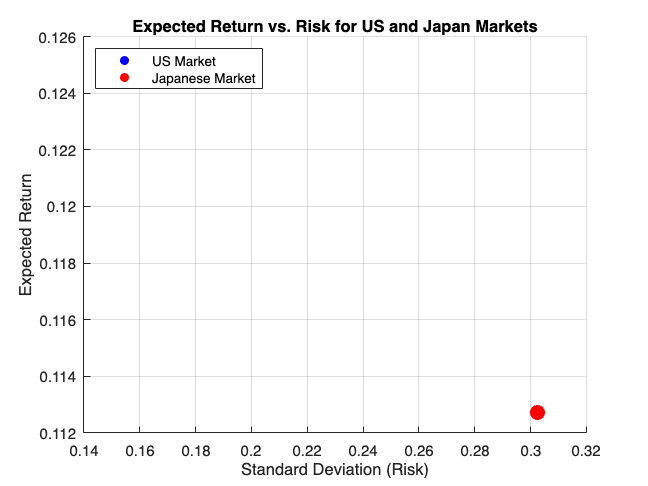

% Define the variables

% US market data
us_return = 0.1246;        % Expected return for US equities
us_stddev = 0.1576;        % Standard deviation for US equities

% Japan market data (adjusted for currency volatility)
japan_return = 0.1127;     % Expected return for Japanese equities
japan_stddev = 0.3025;     % Standard deviation for Japanese equities (adjusted for currency risk)

% Create a figure for the plot
figure;

% Plot US data
scatter(us_stddev, us_return, 100, 'filled', 'b'); % US in blue
hold on;

% Plot Japan data
scatter(japan_stddev, japan_return, 100, 'filled', 'r'); % Japan in red

% Add labels and title
xlabel('Standard Deviation (Risk)');
ylabel('Expected Return');
title('Expected Return vs. Risk for US and Japan Markets');

% Add legend
legend('US Market', 'Japanese Market', 'Location', 'northwest');

% Add grid for better readability
grid on;

% Show the plot
hold off;

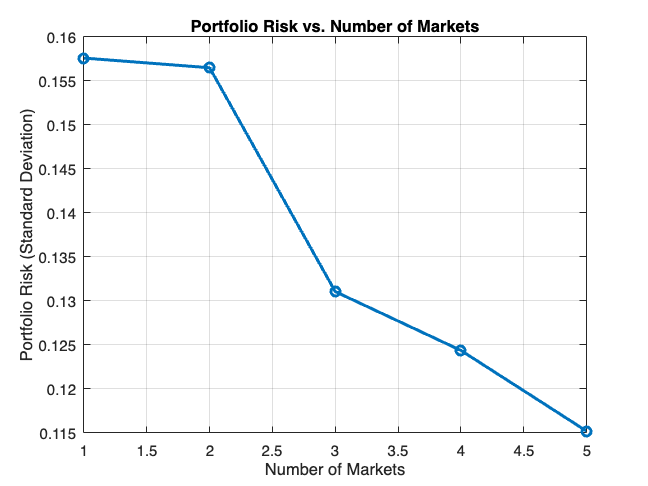

% MATLAB code to plot risk (std deviation) vs. number of markets

% Example covariance matrix for 5 markets
cov_matrix = [
    0.02483, 0.01084, 0.0012, 0.0023, 0.0015;
    0.01084, 0.05143, 0.0121, 0.0131, 0.0082;
    0.0012,  0.0121,  0.0300, 0.0110, 0.0094;
    0.0023,  0.0131,  0.0110, 0.0401, 0.0103;
    0.0015,  0.0082,  0.0094, 0.0103, 0.0255
];

% Example expected returns for the 5 markets
expected_returns = [0.1246, 0.1127, 0.1050, 0.0975, 0.0890];

% Number of markets to evaluate (from 1 to 5 in this case)
num_markets = size(cov_matrix, 1);

% Risk aversion coefficient
risk_aversion = 3.5;

% Initialize an array to store portfolio risk (std deviation)
portfolio_risk = zeros(num_markets, 1);

% Loop through different numbers of markets
for i = 1:num_markets
    % Subset the covariance matrix and expected returns up to i markets
    sub_cov_matrix = cov_matrix(1:i, 1:i);
    sub_expected_returns = expected_returns(1:i);
    
    % Use equally weighted portfolio for simplicity
    weights = ones(i, 1) / i;
    
    % Calculate portfolio variance
    portfolio_variance = weights' * sub_cov_matrix * weights;
    
    % Calculate portfolio risk (std deviation)
    portfolio_risk(i) = sqrt(portfolio_variance);
end

% Plot risk (standard deviation) vs. number of markets
figure;
plot(1:num_markets, portfolio_risk, '-o', 'LineWidth', 2);
xlabel('Number of Markets');
ylabel('Portfolio Risk (Standard Deviation)');
title('Portfolio Risk vs. Number of Markets');
grid on;

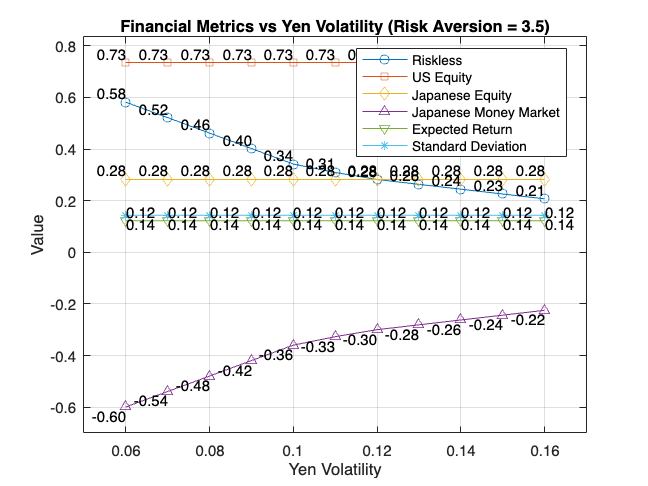

% Define evenly spaced Yen Volatility increments
yen_volatility_consistent = 0.06:0.01:0.16; % Consistent increments of 0.01

% Interpolate the data for Risk Aversion = 3.5
riskless_3_5_interp = interp1(yen_volatility_3_5, riskless_3_5, yen_volatility_consistent, 'linear');
us_equity_3_5_interp = interp1(yen_volatility_3_5, us_equity_3_5, yen_volatility_consistent, 'linear');
japan_equity_3_5_interp = interp1(yen_volatility_3_5, japan_equity_3_5, yen_volatility_consistent, 'linear');
japan_money_market_3_5_interp = interp1(yen_volatility_3_5, japan_money_market_3_5, yen_volatility_consistent, 'linear');
expected_return_3_5_interp = interp1(yen_volatility_3_5, expected_return_3_5, yen_volatility_consistent, 'linear');
standard_deviation_3_5_interp = interp1(yen_volatility_3_5, standard_deviation_3_5, yen_volatility_consistent, 'linear');

% Interpolate the data for Risk Aversion = 2.0
riskless_2_0_interp = interp1(yen_volatility_2_0, riskless_2_0, yen_volatility_consistent, 'linear');
us_equity_2_0_interp = interp1(yen_volatility_2_0, us_equity_2_0, yen_volatility_consistent, 'linear');
japan_equity_2_0_interp = interp1(yen_volatility_2_0, japan_equity_2_0, yen_volatility_consistent, 'linear');
japan_money_market_2_0_interp = interp1(yen_volatility_2_0, japan_money_market_2_0, yen_volatility_consistent, 'linear');
expected_return_2_0_interp = interp1(yen_volatility_2_0, expected_return_2_0, yen_volatility_consistent, 'linear');
standard_deviation_2_0_interp = interp1(yen_volatility_2_0, standard_deviation_2_0, yen_volatility_consistent, 'linear');

% Create plots with interpolated data
create_plot(yen_volatility_consistent, riskless_3_5_interp, us_equity_3_5_interp, japan_equity_3_5_interp, japan_money_market_3_5_interp, expected_return_3_5_interp, standard_deviation_3_5_interp, 3.5);

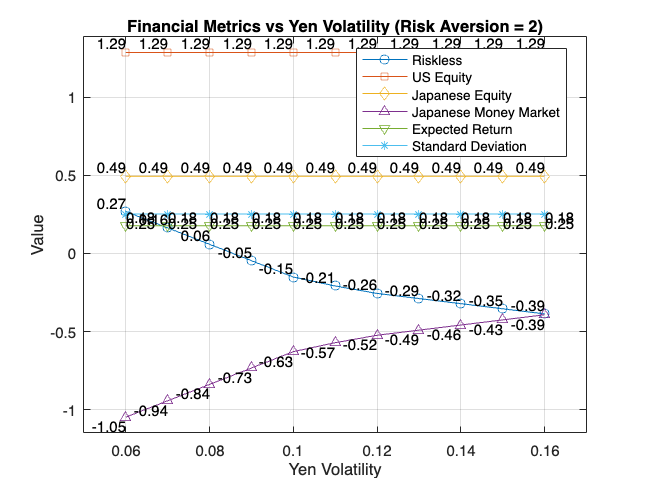

create_plot(yen_volatility_consistent, riskless_2_0_interp, us_equity_2_0_interp, japan_equity_2_0_interp, japan_money_market_2_0_interp, expected_return_2_0_interp, standard_deviation_2_0_interp, 2.0);


% Function to create plot

function create_plot(yen_volatility, riskless, us_equity, japan_equity, japan_money_market, expected_return, standard_deviation, risk_aversion)
    figure;
    plot(yen_volatility, riskless, '-o', 'DisplayName', 'Riskless');
    hold on;
    plot(yen_volatility, us_equity, '-s', 'DisplayName', 'US Equity');
    plot(yen_volatility, japan_equity, '-d', 'DisplayName', 'Japanese Equity');
    plot(yen_volatility, japan_money_market, '-^', 'DisplayName', 'Japanese Money Market');
    plot(yen_volatility, expected_return, '-v', 'DisplayName', 'Expected Return');
    plot(yen_volatility, standard_deviation, '-*', 'DisplayName', 'Standard Deviation');

    xlabel('Yen Volatility');
    ylabel('Value');
    title(['Financial Metrics vs Yen Volatility (Risk Aversion = ', num2str(risk_aversion), ')']);
    legend('Location', 'best');
    grid on;

    xlim([min(yen_volatility)-0.01, max(yen_volatility)+0.01]);
    ylim([min(min(japan_money_market), min(riskless))-0.1, max(max(us_equity), max(japan_equity))+0.1]);

    % Add data labels
    for i = 1:length(yen_volatility)
        text(yen_volatility(i), riskless(i), num2str(riskless(i), '%.2f'), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
        text(yen_volatility(i), us_equity(i), num2str(us_equity(i), '%.2f'), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
        text(yen_volatility(i), japan_equity(i), num2str(japan_equity(i), '%.2f'), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
        text(yen_volatility(i), japan_money_market(i), num2str(japan_money_market(i), '%.2f'), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'right');
        text(yen_volatility(i), expected_return(i), num2str(expected_return(i), '%.2f'), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
        text(yen_volatility(i), standard_deviation(i), num2str(standard_deviation(i), '%.2f'), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');
    end
end

